# Tarea 3 Dinámica de Fluidos Geofísicos 

## Parte A: introducción a la nueva ecuación termodinámica para el agua de mar.

Primero cargamos nuestras bases de datos de las estaciones correspondientes. Luego creamos la siguiente función para interpolar nuestros datos como se muestra en el código.

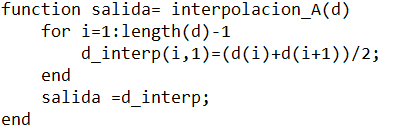

%% cargando datos
d10=readmatrix("KN38D_P06_010.txt");
d12=readmatrix("KN38D_P06_012.txt");
%interpolamos por columna 
%presion
pres10= interpolacion_A(d10(:,1));
pres12= interpolacion_A(d12(:,1));
%temperatura
tem10= interpolacion_A(d10(:,2));
tem12= interpolacion_A(d12(:,2));
%salinidad
sal10= interpolacion_A(d10(:,3));
sal12= interpolacion_A(d12(:,3));

%juntamos nuestras columnas en una matriz nueva para la estacion 10
A=[];
A(:,1)= pres10;
A(:,2)= tem10;
A(:,3)= sal10;
A=[0,16.5671,34.3272;A];

%juntamos nuestras columnas en una matriz nueva para la estacion 12
B=[];
B(:,1)= pres12;
B(:,2)= tem12;
B(:,3)= sal12;
B=[0,16.9528,34.3974;B];

**A1.**- Calcule la salinidad absoluta a partir de la salinidad practica dada en los archivos indicados anteriormente. Use la función:  gsw_SA_from_SP.

Explique y comente el significado (definición) de salinidad práctica y la nueva medida de salinidad absoluta.

%extraemos los datos que necesitamos 
CTDPRS_A= A(:,1);
CTDSAL_A= A(:,3);
long_A= -72.513667; %longitud en grados
lat_A= -32.490137; %latitud en grados

CTDPRS_B= B(:,1);
CTDSAL_B= B(:,3);
long_B= -72.9975;
lat_B= -32.5035;

%calculamos salinidad absoluta 
[SA_A, in_ocean] = gsw_SA_from_SP(CTDSAL_A,CTDPRS_A,long_A,lat_A);
[SA_B, in_ocean] = gsw_SA_from_SP(CTDSAL_B,CTDPRS_B,long_B,lat_B);

`RESPUESTA:`El concepto de salinidad practica es una medida que se utiliza en oceonografia y ciencias ambientales para describir la concentración de sales disueltas en una muestra de agua. Se obtiene a partir de la medición de la conductividad eléctrica del agua de mar. La salinidad puede variar en diferentes áreas del océano y en diferentes profundidades debido a diversos factores, como la evaporación, el derretimiento del hielo, los aportes de agua dulce, entre otros procesos naturales.

La salinidad absoluta se refiere a la concentración total de sales disueltas en una muestra de mar, sin tener en cuenta el efecto de la temperatura y la presión en la densidad del agua, por lo que es una mdida directa de la cantidad de solidos disueltos en agua de mar. Esto significa que dos masas de agua con la misma salinidad practica pueden tener diferentes salinidades absolutas si tienen diferentes temperaturas y presiones. Ya que, la salinidad practica considera la temperatura, presión y se relaciona con la densidad del agua.

**A2.**- Calcule la temperatura conservativa (Q) a partir de *q* (temperatura potencial). Use la función:   gsw_CT_from_pt.  Explique qué representa la temperatura conservativa (Q). 

Grafique los perfiles de temperatura conservativa (versus presión) y salinidad absoluta (versus presión) de las dos estaciones. Grafique la temperatura de las dos estaciones en un mismo gráfico para compararlas, e igualmente para la salinidad.  

Analice los perfiles: Indique si se observa una capa de mezcla, entre que profundidades se encuentra la termoclina y la halocina, comente las diferencias entre sus profundidades, Cual es la variación típica de la temperatura y de la salinidad en la termoclina y en la halocína respectivamente, etc. 

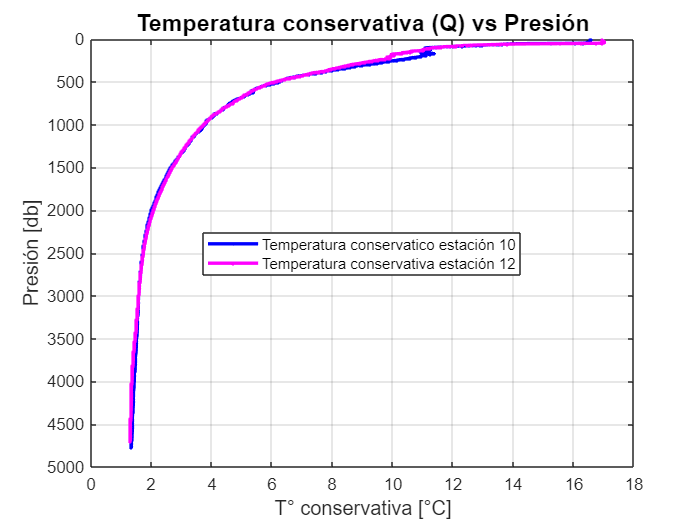

%extraemos los datos que necesitamos 
CTDTMP_A= A(:,2);
CTDTMP_B= B(:,2);

%primero debemos calcular la temperatura potencial
pt_A = gsw_pt_from_t(SA_A,CTDTMP_A,CTDPRS_A);
pt_B = gsw_pt_from_t(SA_B,CTDTMP_B,CTDPRS_B);

%teniendo la temperatura potencial podemos calcular la temperatura
%conservativa (Q)
CT_A = gsw_CT_from_pt(SA_A,pt_A);
CT_B = gsw_CT_from_pt(SA_B,pt_B);

%graficos
figure
plot(CT_A,CTDPRS_A,'b.-',LineWidth=2)
hold on
plot(CT_B,CTDPRS_B,'m.-',LineWidth=2)
axis ij; grid on
title('Temperatura conservativa (Q) vs Presión',FontSize=14)
xlabel('T° conservativa [°C]',FontSize=12);
ylabel('Presión [db]',FontSize=12);
legend('Temperatura conservatico estación 10', 'Temperatura conservativa estación 12', 'Location','best')

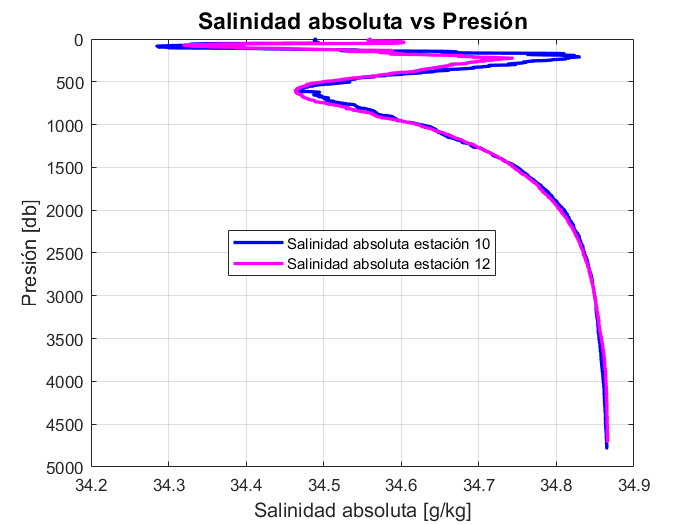

figure
plot(SA_A,CTDPRS_A,'b.-',LineWidth=2)
hold on
plot(SA_B,CTDPRS_B,'m.-',LineWidth=2)
axis ij; grid on
title('Salinidad absoluta vs Presión',FontSize=14)
xlabel('Salinidad absoluta [g/kg]',FontSize=12);
ylabel('Presión [db]',FontSize=12);
legend('Salinidad absoluta estación 10', 'Salinidad absoluta estación 12', 'Location','best')

`RESPUESTA:`Para poder indicar si es que hay una capa de mezcla primero definiremos este concepto, es una capa de agua en la que la densidad es homogénea debido a la mezcla de diferentes masas de agua co diferentes propiedades (temperatura y salinidad). En esta capa, las propiedades del agua s mezclan y se vuelven uniformes, lo que resulta en densidad homogénea. La capa de mezcla se encuentra en la parte superior del océano y puede ser influenciada por factores como el viento, temperatura y salinidad. Dado este concepto y viendo los gráficos podemos decir que si hay una capa de mezcla que se encuentra en los 50 dB de presión (0-50).

La termoclina es una capa en el océano en la que la temperatura disminuye rápidamente con la profundidad. Es una capa en la que hay un cambio abrupto en la temperatura del agua, s encuentra en la parte inferior de la capa de mezcla y puede ser influenciada por diversos factores (radiación solar, temperatura y salinidad). Podemos ver que en este caso ocurre termoclina entre las presiones 50-150 dB aproximadamente, donde se ve un cambio abrupto en la temperatura conservativa de 16 °C a los 10 °C.

La halocina es una capa en el océano en la que la salinidad cambia rápidamente con la profundidad. Es una capa en la que hay un cambio abrupto en la salinidad del agua, se encuentra debajo de la capa de mezcla y puede ser influenciada por diversos factores (evaporación, precipitación y derritiminto de los glaciales). Podemos notar que ocurren 2 halocinas en cada estación. En la estación 10 podemos ver que las halocinas se encuentran entre las 50-

**A3.**- Use la función gsw_SA_CT_plot para graficar la salinidad absoluta versus la temperatura conservativa. Incluya en el gráfico las isopicnas correspondientes para una adecuada visualización. 

¿Cuál de las estaciones contiene una mayor proporción de Agua Ecuatorial Subsuperficial? ¿Cuál es la densidad potencial que caracteriza esta masa de agua en la región? (consulte con el ayudante por referencias para orientar su respuesta). 

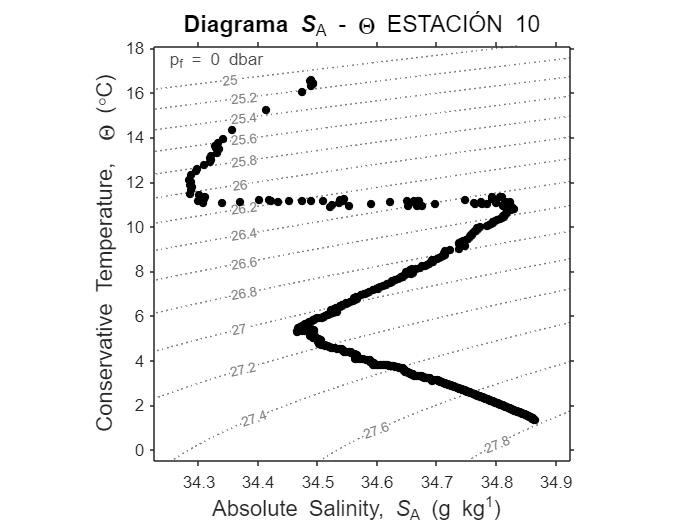

figure
gsw_SA_CT_plot(SA_A,CT_A,0,(25:0.2:30),'Diagrama \it{S}\rm_A - {\Theta} ESTACIÓN 10')

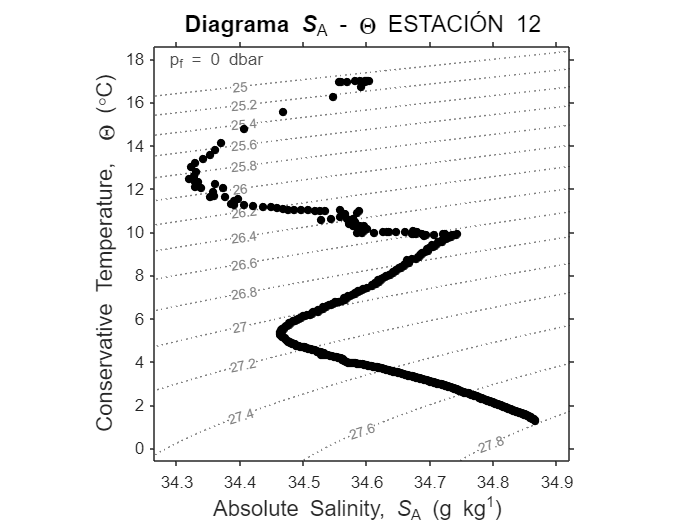

figure
gsw_SA_CT_plot(SA_B,CT_B,0,(25:0.2:30),'Diagrama \it{S}\rm_A - {\Theta} ESTACIÓN 12')

`RESPUESTA:`El Agua Ecuatorial Subsuperficial (AESS) es una masa de agua que se encuentra bajo la superficie del océano y es transportada hacia el sur a lo largo de la costa por la Corriente Subsuperficial de Perú-Chile. Esta masa de agua se caracteriza por ser relativamente cálida, salina, con un muy bajo contenido de oxígeno disuelto y rica en nutrientes. Para reconocer en un gráfico de temperatura vs salinidad cuál de las dos estaciones contiene una mayor proporción de Agua Ecuatorial Subsuperficial (AESS), se debe buscar en el gráfico la región donde se encuentra la AESS, que se caracteriza por tener una temperatura relativamente cálida y una salinidad alta. Luego, debemos comparar la posición de esta región en los dos gráficos de las estaciones que se están comparando. 

Dada su definición y los gráficos obtenidos, se pude observar que en la estación 10 contiene una mayor proporción de AESS, ya que, la región correspondiente está desplazada hacía la derecha y hacía arriba en comparación con la estación 12.

**6A.**- Usando la nueva ecuación de estado, calcule la densidad potencial en cada estación usando como presión de referencia la superficie (presión cero). Grafique los perfiles (figuras densidad potencial versus presión para ambas estaciones). 

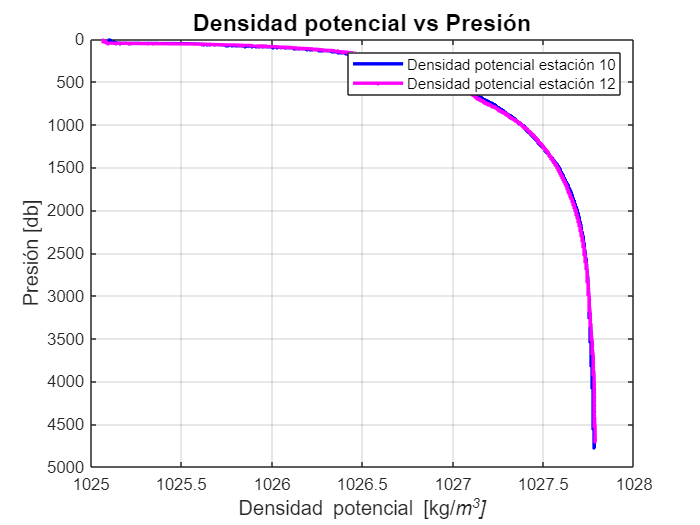

%calculamos densidad potencial 
pot_rho_t_exact_A = gsw_pot_rho_t_exact(SA_A,CTDTMP_A,CTDPRS_A,0);
pot_rho_t_exact_B = gsw_pot_rho_t_exact(SA_B,CTDTMP_B,CTDPRS_B,0);

%graficamos
figure()
plot(pot_rho_t_exact_A,CTDPRS_A,'b.-',LineWidth=2)
hold on
plot(pot_rho_t_exact_B,CTDPRS_B,'m.-',LineWidth=2)
axis ij; grid on
title('Densidad potencial vs Presión',FontSize=14)
xlabel('Densidad potencial [kg/\it{m}^3]',FontSize=12);
ylabel('Presión [db]',FontSize=12);
legend('Densidad potencial estación 10', 'Densidad potencial estación 12')

Integre numéricamente (usando trapz.m) la densidad de cada estación entre la superficie y los 1000 db (note que el intervalo de la presión en los datos es de 2 db)  

%integrar la densidad de cada estación entre la superficie y los 1000 db
[x,y] = find(CTDPRS_A==1000); %buscamos la posicion donde hay una presion de 1000 db
format long
RHO_A= trapz(CTDPRS_A(1:x,1), pot_rho_t_exact_A(1:x,1))

RHO_A =      1.026828975020514e+06



RHO_B= trapz(CTDPRS_B(1:x,1), pot_rho_t_exact_B(1:x,1))

RHO_B =      1.026831281902829e+06


¿Dada la diferencia de densidades que existe entre las estaciones en qué estación esperaría que la columna de agua fuese más alta para generar los 1000 db?  

Considere que la isobara de 1000 db está perfectamente horizontal (es decir que el gradiente de presión horizontal es cero en 1000 db) ¿en qué estación el nivel del mar debería estar más elevado para que la isobara de 1000 db sea completamente horizontal?   

`RESPUESTA:`Primero notar que las densidades para cada estación son

Estación 10: 1.0268289 E+06

Estación 12: 1.0268312 E+06

Con estos valores de densidad proporcionados, podemos observar que la estación 12 tiene una densidad levemente mayor en comparación con la estación 10. La estación 12 al tener mayor densidad, tiene mayor presión por lo que podriamos decir que tiene mayor cantidad de agua, por lo tanto su columna de agua sería de mnor altura. En cambio, la estacion 10 tiene menor densidad, podemos interpretar que tiene 'menor peso' por lo que ncesita mayor cantidad d agua para generar los 1000 dBar, por lo que decimos que su columna de agua es mayor. 

Puedo concluir que, para que la isobara de 1000 dBar sea completamente horizontal, se requiere que el nivel de mar sea más elevado en la estación 10, para compensar la diferencia en las densidades y así mantener la presion constante entre las dos estaciones.

## Parte B: Cálculo de velocidad geostrófica.

**1****B**.- Obtenga la *anomalía del volumen específico* (d) en cada estación  

Usando la función: gsw_specvol_anom_standard(SA,CT, p) donde SA, CT y p son salinidad absoluta, temperatura conservativa y presión (en decibares “db”) respectivamente.  

%obtenemos anomalias del volumen especifico de cada estación
specvol_anom_A = gsw_specvol_anom_standard(SA_A,CT_A,CTDPRS_A);
specvol_anom_B = gsw_specvol_anom_standard(SA_B,CT_B,CTDPRS_B);

**2B**.- Construya una tabla similar a la tabla dada en el libro de Pond & Pickard (1982; ver tabla más abajo), usando los valores de las estaciones oceanográficas dadas. Incluya una columna para la presión y otra para profundidad. Use las profundidades estándares en oceanografía para construir la tabla (ver por ejemplo [https://www.nodc.noaa.gov/OC5/WOA01/cdwoa01.html](https://www.nodc.noaa.gov/OC5/WOA01/cdwoa01.html)). Use la subrutina (o función) adecuada para calcular la profundidad (en m) a partir de la presión (en db). El valor de st corresponde a la densidad in situ -1000 (use gsw_rho con los argumentos correspondientes para obtener esta densidad).  

Obtenga d directamente, como se indicó en el punto anterior (no incluya en su tabla los valores de la anomalía termoestérica (∆S,T) ni los deltas: dT,P  dS,P que aparecen en la Table del Libro Pond & Pickard).  Note que  d_barra es un valor promedio entre las dos profundidades (o presiones) y ∆p es la diferencia de presiones. 

%otenemos profundidad
z_A = gsw_z_from_p(CTDPRS_A,lat_A);
z_B = gsw_z_from_p(CTDPRS_B,lat_B);

%obtenemos valor de densidad in situ -1000
rho_A = gsw_rho(SA_A,CT_A,CTDPRS_A);
rho_B = gsw_rho(SA_B,CT_B,CTDPRS_B);
rho_A= rho_A -1000;

Unrecognized function or variable 'rho_A1'.

rho_B= rho_B1 -1000;

% Buscamos posiciones para profundidades estandares en oceonografía 
depthh= [1, 6, 11, 16, 26, 38, 51, 63, 76, 101, 126, 151, 201, 251, 301, 351, 401, 451, 501, 551, 601, 651, 701, 751, 876, 1001, 1251, 1501, 1751, 2001, 2251];

%estacion 10
depth_a=z_A(depthh);
depth_A= -(round(depth_a, 2));
pressure_A= CTDPRS_A(depthh);
tempeture_A= CTDTMP_A(depthh);
salinity_A=CTDSAL_A(depthh);
density_A=rho_A(depthh);
specvol_A=specvol_anom_A(depthh);

a1= [depth_A, pressure_A, tempeture_A, salinity_A, density_A, specvol_A];

%estacion 12
depth_b=z_B(depthh);
depth_B= -(round(depth_b, 2));
pressure_B= CTDPRS_B(depthh);
tempeture_B= CTDTMP_B(depthh);
salinity_B=CTDSAL_B(depthh);
density_B=rho_B(depthh);
specvol_B=specvol_anom_B(depthh);

b1= [depth_B, pressure_B, tempeture_B, salinity_B, density_A, specvol_B];

%volumen especifico promedio
%estacion 10

for i=1:(length(specvol_A)-1)
    specvolprom_a(i)=(specvol_A(i) + specvol_A(i+1)) /2;
end
specvolprom_A= specvolprom_a';
specvolprom_A(31,1)= NaN;

%estacion 12
for i=1:(length(specvol_B)-1)
    specvolprom_b(i)=(specvol_B(i) + specvol_B(i+1)) /2;
end
specvolprom_B= specvolprom_b';
specvolprom_B(31,1)= NaN;

%diferencia de presiones 
%estacion 010
for i=1:(length(pressure_A)-1)
    difpresion_a(i)=(pressure_A(i+1) - pressure_A(i));
end
difpresion_A=difpresion_a';
difpresion_A(31,1)= NaN;

%estacion 12
for i=1:(length(pressure_A)-1)
    difpresion_b(i)=(pressure_B(i+1) - pressure_B(i));
end
difpresion_B= difpresion_b';
difpresion_B(31,1)= NaN;

%multiplicación delta barra con la diferencia de presiones
producto_A= (specvolprom_A .* difpresion_A)*10000; % cambiamos las unidades de medida
producto_B= (specvolprom_B .* difpresion_B)*10000;


A1= [depth_A, pressure_A, tempeture_A, salinity_A, density_A, specvol_A, specvolprom_A, difpresion_A, producto_A];
B1= [depth_B, pressure_B, tempeture_B, salinity_B, density_A, specvol_B, specvolprom_B, difpresion_B, producto_B];

%creamos una tabla
table1= table(depth_A, pressure_A, tempeture_A, salinity_A, density_A, specvol_A, specvolprom_A, producto_A, VariableNames={'Depth', 'Pressure', 'T°','Salinity','Density','Anomalies','Average anomalies','producto'});
disp(table1)
table2= table(depth_B, pressure_B, tempeture_B, salinity_B, density_B, specvol_B, specvolprom_B, producto_B, VariableNames={'Depth', 'Pressure', 'T°','Salinity','Density','Anomalies','Average anomalies','producto'});
disp(table2)

**3B**.- Integre **numéricamente** las anomalías del volumen específico entre los distintos pares de isóbaras (entre 1500 db y cada nivel de presión hasta la superficie) para obtener la anomalía geopotencial (puede usar los valores de la tabla directamente sumando la penúltima columna, como en la tabla del ejemplo. Se debe tener cuidado en la integración si las presiones no están equi-espaciadas). Si es necesario *extrapole* linealmente los valores hasta *p* = 0.  

   

Indique en cuál de las dos estaciones la altura dinámica (respecto de 1500 db) es mayor. Dada esta diferencia de alturas (y suponiendo que la isobara a 1500 db es horizontal), ¿en qué dirección debería ser la velocidad geostrófica superficial (hacia el norte o hacia el sur)?    

%estacion 010 cortar datos
cortepresion_A=CTDPRS_A(1:751,1);

for i=1:(length(specvol_anom_A)-1)
    specvol_anomprom_A1(i)=(specvol_anom_A(i) + specvol_anom_A(i+1)) /2;
end
specvol_anomprom_A=specvol_anomprom_A1';
cortedeltabarra_A= specvol_anomprom_A(1:751,1);

%estacion 012 cortar datos
cortepresion_B=CTDPRS_B(1:751,1);

for i=1:(length(specvol_anom_B)-1)
    specvol_anomprom_B1(i)=(specvol_anom_B(i) + specvol_anom_B(i+1)) /2;
end
specvol_anomprom_B=specvol_anomprom_B1';
cortedeltabarra_B= specvol_anomprom_B(1:751,1);

%calculamos anomalia geopotencial 
AGP_A= (cortedeltabarra_A .*2); % multiplicamos por 2 porque la distancia entre presiones es siempre 2
AGP_B= (cortedeltabarra_B .*2);

AGP_A= flipud(AGP_A); % Damos vuelta nuestra columna para facilitar el calculo de la sumatoria
AGP_B= flipud(AGP_B);

AGP_A= cumsum(AGP_A(:,1)); %Sumatoria
AGP_B= cumsum(AGP_B(:,1));

AGP_A= flipud(AGP_A); % Damos vuelta nuevamente nuestra columna 
AGP_B=flipud(AGP_B);

AGP_A=AGP_A.*10000; % cambiamos las unidades de medida
AGP_B=AGP_B.*10000;

`RESPUESTA:`Para saber cuál estación tiene la mayor altura dinámica nos fijamos en la primera fila de nuestros valores obtenidos (AGP_A Y AGP_B), ya que, la primera fila representa la multiplicación entre la superficie y los 1500 db. Podemos notar que la estación con mayor altura es la estación 10 con una altura dinámica de 16.15 aproximadamente. 

La estación 10 se caracteriza por tener una mayor altura dinámica en comparación con la estación 12, esta diferencia de altura da lugar a que la estación 10 tenga un gradiente de presión que se extiende hacia la estación 12. Al observar esto en un mapa, podemos ver que la estación 12 se encuentra al oeste de la estación 10, como resultado la dirección del gradiente de presión apunta hacía el oeste. 

Considerando la influencia de la fuerza de Coriolis en el hemisferio sur, la cual induce un movimiento hacía el este, y teniendo en cuenta que la velocidad geopotencial se desplaza hacía la izquierda de este, por lo que podemos deducir que la velocidad geostrófica superficial se dirigirá hacia el sur.

**4B**.- Dadas las posiciones geográficas calcule la distancia entre las estaciones. Indique y explique el método que utilizó para calcular distancia entre dos puntos sobre la Tierra. Note que el paquete The Gibbs SeaWater (GSW) Oceanographic Toolbox tiene una opción. 

%calculamos de forma manual
% Convertir latitud y longitud de grados a radianes
latitud1 = deg2rad(lat_A);
longitud1 = deg2rad(long_A);
latitud2 = deg2rad(lat_B);
longitud2 = deg2rad(long_B);
% Calcular diferencias
delta_latitud = latitud2 - latitud1;
delta_longitud = longitud2 - longitud1;
% Aplicar fórmula de Haversine
a = sin(delta_latitud/2)^2 + cos(latitud1) * cos(latitud2) * sin(delta_longitud/2)^2;
c = 2 * atan2(sqrt(a), sqrt(1-a));
radio_tierra= 6371;
% Calcular distancia
distancia_M = radio_tierra * c
%para calcular la distancia entre al estación 10 y 12 creamos una matriz
%con la latitud y longitud de ambas estaciones
long= [long_A long_B];
lat= [lat_A lat_B];
%teniendo las matrices, ocupamos la función de  The Gibbs SeaWater (GSW)
%Oceanographic Toolbox para calcular la distancia
distancia = gsw_distance(long,lat)

**5B**.- Obtenga la variación de la velocidad geostrófica entre dos niveles de presión p1 y p2 mediante la relación 

 

Donde los subíndices A y B denotan las dos estaciones separadas una distancia *L* y *f* es el parámetro de Coriolis evaluado a una latitud promedio entre ambas estaciones. Suponiendo que la velocidad en 1500 db  es cero, obtenga la velocidad *V* en los distintos niveles e incluya estos valores en una Tabla. 

%para calcular la velocidad geostrofica necesitamos obtener previamente los siguientes valores
%calculamos latitud promedio 
latprom= (lat_A + lat_B) /2;
latrad=(latprom*pi)/180; %pasamos la latitud de grados a radianes
%calculamos f coriolis 
vangular= 7.292*10.^(-5);
fcoriolis=2*vangular*sin(latrad);
L=distancia;

%posiciones de profundidad estandar hasta los 1500
depthh2= [1, 6, 11, 16, 26, 38, 51, 63, 76, 101, 126, 151, 201, 251, 301, 351, 401, 451, 501, 551, 601, 651, 701, 751];
pressure2= CTDPRS_A(depthh2);
AGP_10=AGP_A(depthh2);
AGP_10= round(AGP_10,4);
AGP_12= AGP_B(depthh2);
AGP_12= round(AGP_12,4);
AGP_10(24,1)=0;
AGP_12(24,1)=0;

% calculamos dv
for i= 1:length(AGP_12)
    dv(i,1)= (1/(L*fcoriolis))*(AGP_10(i)-AGP_12(i));
end

dv=flipud(dv);

%calculamos v en cada nivel
V(1)=0;
for i= 2:length(dv)
    V(i,1)= dv(i) + V(i-1);
end

V= flipud(V);

table3= table(pressure2, AGP_10, AGP_12, V, VariableNames={'Pressure [dbar]', 'geopotential anomaly E010','geopotential anomaly E012', 'Speed at different levels'});
disp(table3)

**6B.**- Grafique la velocidad geostrófica entre las estaciones A y B versus presión. INTERPRETE Y COMENTE EL GRÁFICO. 

figure
plot(V,pressure2,'m', LineWidth=2)
axis ij; grid on
title('Velocidad geostrófica vs Presión')
xlabel('Velocidad [m/\it{s}^2]',FontSize=12);
ylabel('Presión [db]',FontSize=12);

`RESPUESTA:` Se puede notar que la velocidad aumenta rapidamente con la profundidad en direccion este (velocidad positiva)